# Human Activity Recognition Simulink Model for Smartphone Deployment

This example shows how to prepare a Simulink® model that classifies human activity based on smartphone sensor signals for code generation and smartphone deployment. The example provides two Simulink models that are ready for deployment to an Android™ device and an iOS device. After you install the required support package for a target device, train the classification model and deploy the Simulink model to the device. 

## Load Sample Data Set

Load the `humanactivity` data set.

load humanactivity

The `humanactivity` data set contains 24,075 observations of five different physical human activities: Sitting, Standing, Walking, Running, and Dancing. Each observation has 60 features extracted from acceleration data measured by smartphone accelerometer sensors. The data set contains the following variables:

- `actid` — Response vector containing the activity IDs in integers: 1, 2, 3, 4, and 5 representing Sitting, Standing, Walking, Running, and Dancing, respectively

- `actnames` — Activity names corresponding to the integer activity IDs

- `feat` — Feature matrix of 60 features for 24,075 observations

- `featlabels` — Labels of the 60 features

The Sensor HAR (human activity recognition) App [1] was used to create the `humanactivity` data set. When measuring the raw acceleration data with this app, a person placed a smartphone in a pocket so that the smartphone was upside down and the screen faced toward the person. The software then calibrated the measured raw data accordingly and extracted the 60 features from the calibrated data. For details about the calibration and feature extraction, see [2] and [3], respectively. The Simulink models described later also use the raw acceleration data and include blocks for calibration and feature extraction. 

## Prepare Data

This example uses 90% of the observations to train a model that classifies the five types of human activities and 10% of the observations to validate the trained model. Use [`cvpartition`](docid:stats_ug.brxwayf-1) to specify a 10% holdout for the test set.

rng('default') % For reproducibility
Partition = cvpartition(actid,'Holdout',0.10);
trainingInds = training(Partition); % Indices for the training set
XTrain = feat(trainingInds,:);
YTrain = actid(trainingInds);
testInds = test(Partition); % Indices for the test set
XTest = feat(testInds,:);
YTest = actid(testInds);

Convert the feature matrix `XTrain` and the response vector `YTrain` into a table to load the training data set in the Classification Learner app.

tTrain = array2table([XTrain YTrain]);

Specify the variable name for each column of the table.

tTrain.Properties.VariableNames = [featlabels' 'Activities'];

## Train Boosted Tree Ensemble Using Classification Learner App

Train a classification model by using the Classification Learner app. To open the Classification Learner app, enter `classificationLearner` at the command line. Alternatively, click the **Apps** tab, and click the arrow at the right of the **Apps** section to open the gallery. Then, under **Machine Learning and Deep Learning**, click **Classification Learner**.

On the **Classification Learner** tab, in the **File** section, click **New Session** and select **From Workspace**. 

In the New Session from Workspace dialog box, click the arrow for **Data Set Variable**, and then select the table `tTrain`. Classification Learner detects the predictors and the response from the table.

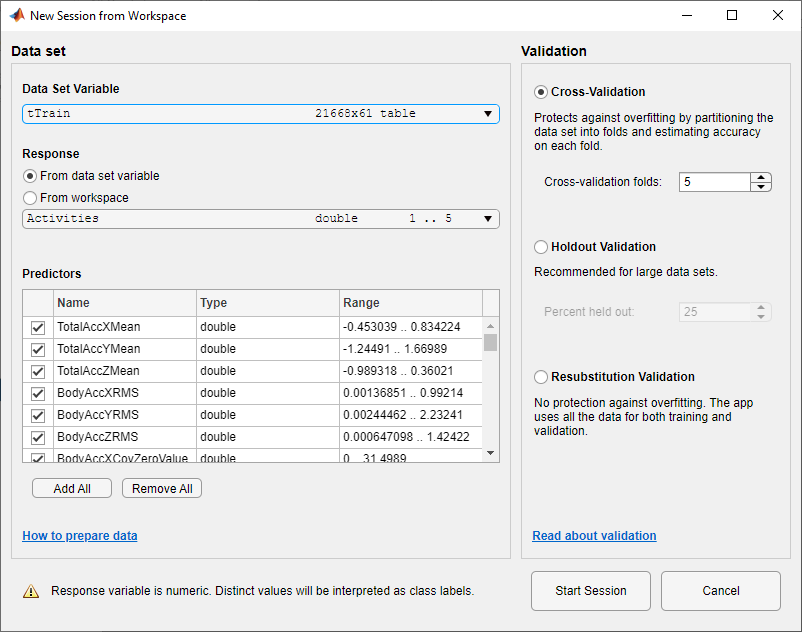

The default option is 5-fold cross-validation, which protects against overfitting. Click **Start Session**. Classification Learner loads the data set and plots a scatter plot of the first two features.

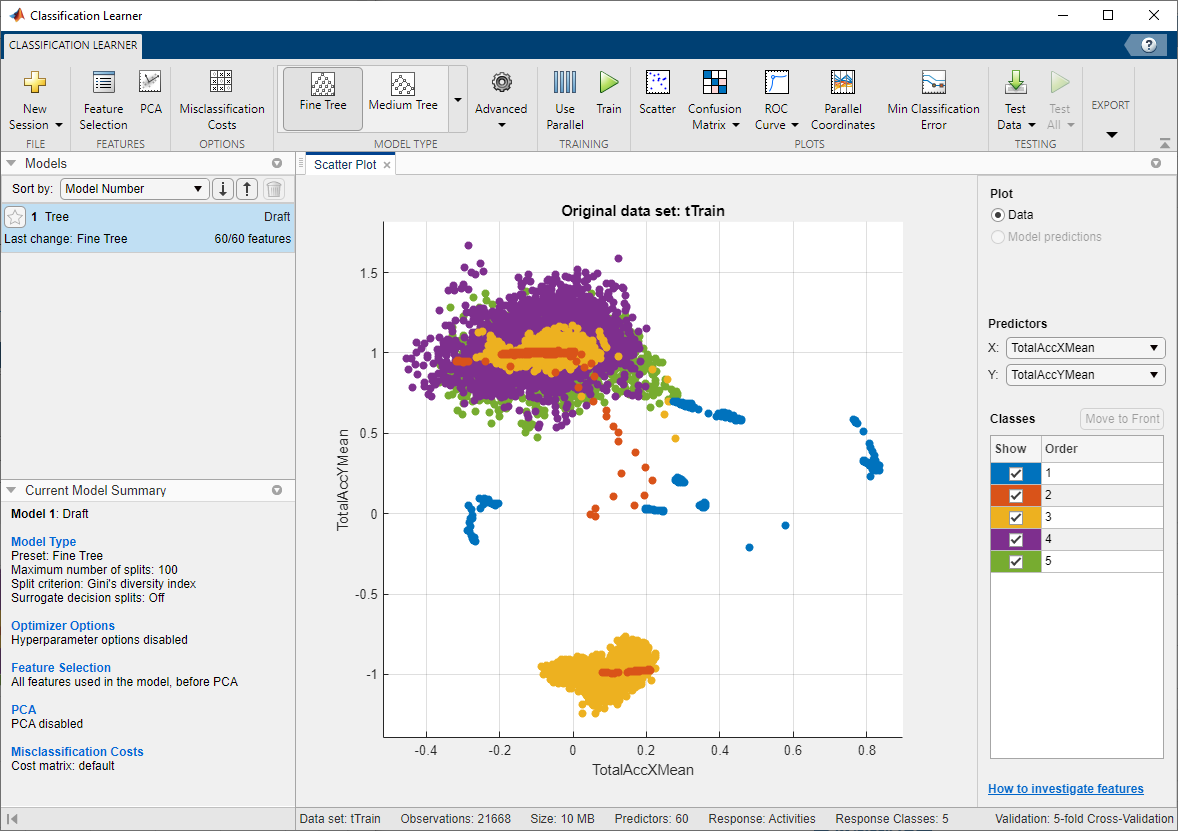

On the **Classification Learner** tab, click the arrow at the right of the **Model Type** section to open the gallery. Then, under **Ensemble Classifiers**, click **Boosted Trees**.

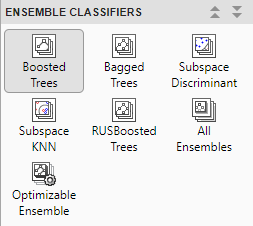

The **Current Model Summary** pane displays the default settings of the boosted tree ensemble model.

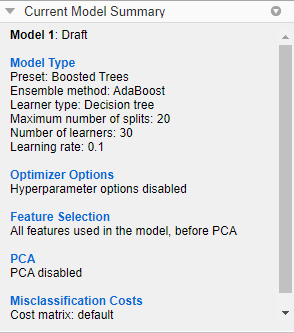

On the **Classification Learner** tab, in the **Training** section, click **Train**. When the training is complete, the **Models** pane displays the 5-fold, cross-validated classification accuracy.

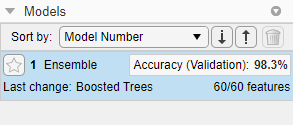

On the **Classification Learner** tab, in the **Export** section, click **Export Model**, and then select **Export Compact Model**. Click **OK** in the dialog box. The structure `trainedModel` appears in the MATLAB® Workspace. The field `ClassificationEnsemble` of `trainedModel` contains the compact model. Extract the trained model from the structure.

## Train Boosted Tree Ensemble at Command Line

Alternatively, you can train the same classification model at the command line. 

template = templateTree('MaxNumSplits',20,'Reproducible',true);
classificationEnsemble = fitcensemble(XTrain,YTrain, ...
    'Method','AdaBoostM2', ...
    'NumLearningCycles',30, ...
    'Learners',template, ...
    'LearnRate',0.1, ...
    'ClassNames',[1; 2; 3; 4; 5]);

Perform 5-fold cross-validation for `classificationEnsemble` and compute the validation accuracy.

partitionedModel = crossval(classificationEnsemble,'KFold',5);
validationAccuracy = 1-kfoldLoss(partitionedModel)

## Evaluate Performance on Test Data

Evaluate performance on the test data set.

testAccuracy = 1-loss(classificationEnsemble,XTest,YTest)

The trained model correctly classifies 97.59% of the human activities on the test data set. This result confirms that the trained model does not overfit to the training data set. 

Note that the accuracy values can vary slightly depending on your operating system. 

## Save Trained Model

For code generation including a classification model object, use [`saveLearnerForCoder`](docid:stats_ug.bvclu99) and [`loadLearnerForCoder`](docid:stats_ug.bvcl05n-1). 

Save the trained model by using [`saveLearnerForCoder`](docid:stats_ug.bvclu99).

saveLearnerForCoder(classificationEnsemble,'EnsembleModel.mat');

The function block **predictActivity** in the Simulink models loads the trained model by using [`loadLearnerForCoder`](docid:stats_ug.bvcl05n-1) and uses the trained model to classify new data.

## Deploy Simulink Model to Device

Now that you have prepared a classification model, you can open the Simulink model, depending on which type of smartphone you have, and deploy the model to your device. Note that the Simulink model requires the `EnsembleModel.mat` file and the calibration matrix file `slexHARAndroidCalibrationMatrix.mat` or `slexHARiOSCalibrationMatrix.mat`. If you click the button located in the upper-right section of this page and open this example in MATLAB, then MATLAB opens the example folder that includes these calibration matrix files. 

Type `slexHARAndroidExample` to open the Simulink model for Android deployment.

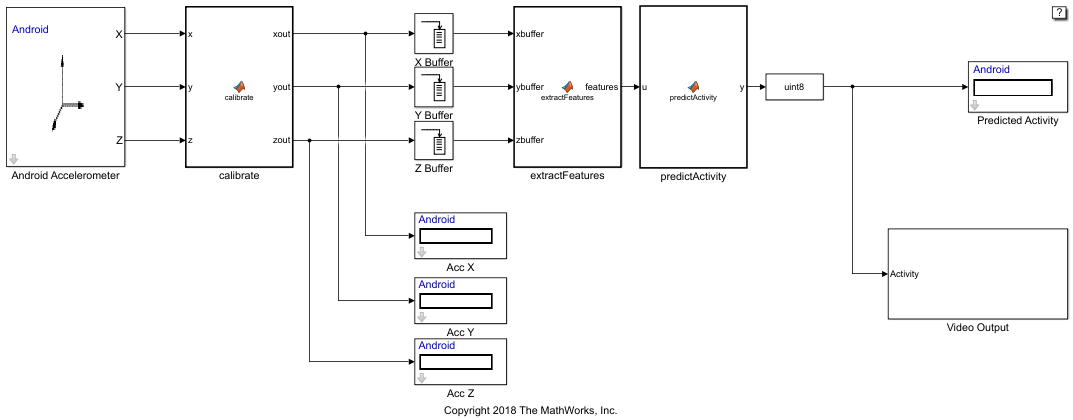

Type `slexHARiOSExample` to open the Simulink model for iOS deployment. You can open the model on the Mac OS platform.

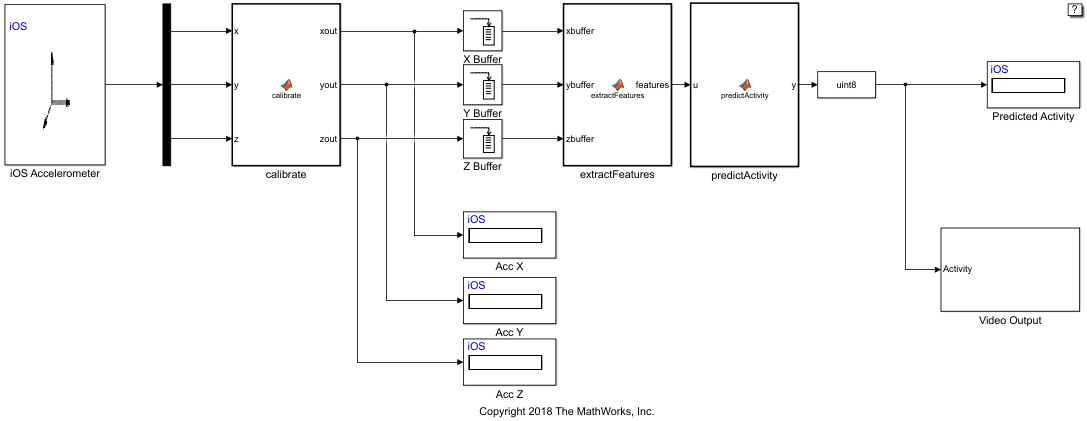

The two Simulink models classify human activity based on acceleration data measured by a smartphone sensor. The models include the following blocks:

- The **Accelerometer** block receives raw acceleration data from accelerometer sensors on the device.

- The **calibrate** block is a MATLAB Function block that calibrates the raw acceleration data. This block uses the calibration matrix in the `slexHARAndroidCalibrationMatrix.mat` file or the `slexHARiOSCalibrationMatrix.mat` file. If you click the button located in the upper-right section of this page and open this example in MATLAB, then MATLAB opens the example folder that includes these files. 

- The display blocks **Acc X**, **Acc Y**, and **Acc Z** are connected to the **calibrate** block and display calibrated data points for each axis on the device.

- Each of the **Buffer** blocks, **X Buffer**, **Y Buffer**, and **Z Buffer**, buffers 32 samples of an accelerometer axis with 12 samples of overlap between buffered frames. After collecting 20 samples, each **Buffer** block joins the 20 samples with 12 samples from the previous frame and passes the total 32 samples to the **extractFeatures** block. Each **Buffer** block receives an input sample every 0.1 second and outputs a buffered frame including 32 samples every 2 seconds.

- The **extractFeatures** block is a MATLAB Function block that extracts 60 features from a buffered frame of 32 accelerometer samples. This function block uses DSP System Toolbox™ and Signal Processing Toolbox™.

- The **predictActivity** block is a MATLAB Function block that loads the trained model from the `EnsembleModel.mat` file by using [`loadLearnerForCoder`](docid:stats_ug.bvcl05n-1) and classifies the user activity using the extracted features. The output is an integer between 1 and 5, corresponding to Sitting, Standing, Walking, Running, and Dancing, respectively.

- The **Predicted Activity** block displays the classified user activity values on the device.

- The **Video Output** subsystem uses a multiport switch block to choose the corresponding user activity image data to display on the device. The **Convert to RGB** block decomposes the selected image into separate RGB vectors and passes the image to the **Activity Display** block. 

To deploy the Simulink model to your device, follow the steps in [Run Model on Android Devices](docid:android_ug#bt9oidb-8) or [Run Model on Apple iOS Device](docid:ios_ug#bt9oidb-8). Run the model on your device, place the device in the same way as described earlier for collecting the training data, and try the five activities. The model displays the classified activity accordingly.

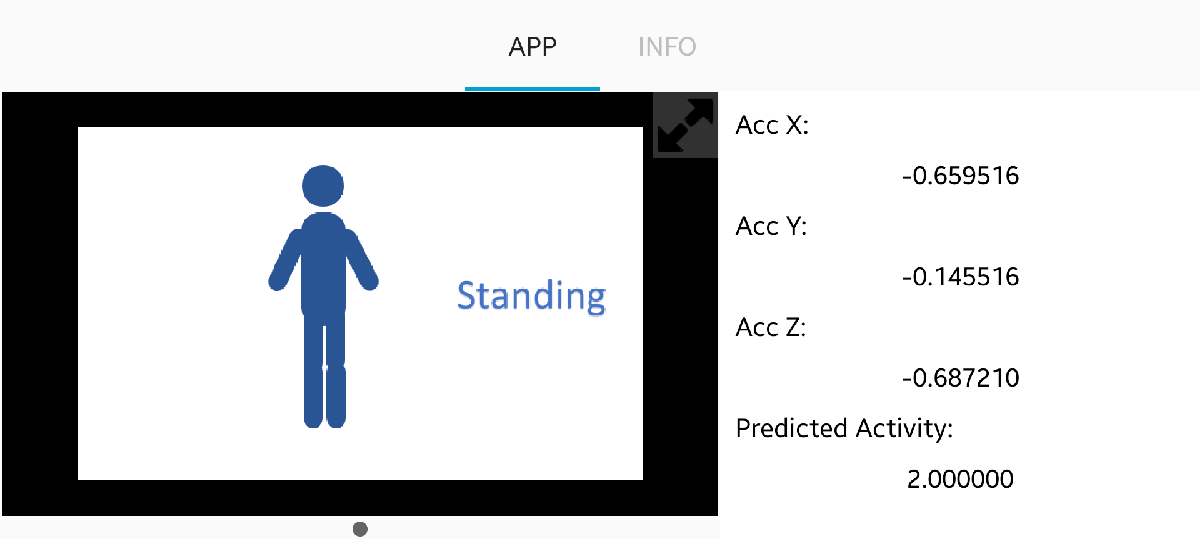

To ensure the accuracy of the model, you need to place your device in the same way as described for collecting the training data. If you want to place your device in a different location or orientation, then collect the data in your own way and use your data to train the classification model.    

The accuracy of the model can be different from the accuracy of the test data set (`testaccuracy`), depending on the device. To improve the model, you can consider using additional sensors and updating the calibration matrix. Also, you can add another output block for audio feedback to the output subsystem using Audio Toolbox™. Use a ThingSpeak™ write block to publish classified activities and acceleration data from your device to the Internet of Things. For details, see [https://thingspeak.com/.](https://thingspeak.com/.)

## References

[1] El Helou, A. Sensor HAR recognition App. MathWorks File Exchange [https://www.mathworks.com/matlabcentral/fileexchange/54138-sensor-har-recognition-app](https://www.mathworks.com/matlabcentral/fileexchange/54138-sensor-har-recognition-app)

[2] STMicroelectronics, AN4508 Application note. “Parameters and calibration of a low-g 3-axis accelerometer.” 2014.

[3] El Helou, A. Sensor Data Analytics. MathWorks File Exchange [https://www.mathworks.com/matlabcentral/fileexchange/54139-sensor-data-analytics--french-webinar-code-](https://www.mathworks.com/matlabcentral/fileexchange/54139-sensor-data-analytics--french-webinar-code-)

*Copyright 2018 The MathWorks, Inc.*